clear all
addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

species='Humans'; 

plot_indiv_subj=0; % turn on/off single subject graphs

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

% Labels for allvisual-
% IMPORTANT: some subjects might not have all ROIs
if strcmp(species,'Humans')
    % these numbers correspond to visual area labels (second column of roi)
    allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
    allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','V7','LO1','LO2','TO1','TO2'};
    % these numbers correspond to color-coded grouping of brain areas in plots
    EVCrois=1:6;
    V4rois=7;
    ventralrois=8:11;
    dorsalrois=12:14;
    lateralrois=15:18;
    allrois = {EVCrois;V4rois;ventralrois;dorsalrois;lateralrois};
    use_colorscale=[0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
    use_colorscale_unique = unique(use_colorscale,'stable','rows');
elseif strcmp(species,'Monks')
     allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,52,53,54,55,56,100,101,102,103];
     allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};       
     EVCrois=1:6;
     V4rois=7:10;
     ventralrois=11:15;
     dorsalrois=16:22;
     lateralrois=23:26;
     allrois = {EVCrois;V4rois;ventralrois;dorsalrois;lateralrois};
     use_colorscale=[0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 1; 1 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
     use_colorscale_unique = unique(use_colorscale,'rows');
else
   fprintf('Error. Unknown species.\n')
end

nodearea_smoothwm_col=2;
nodearea_pial_col=3;

% This should be a more efficient way of filtering the directories:
files = dir(data_dir);
names = {files.name}; 
dirFlags = [files.isdir] & ~strcmp(names, '.') & ~strcmp(names, '..') & ~strcmp(names, 'phasemaps') & ~strcmp(names, 'VTPM') & ~strcmp(names, 'VTPM_delayedsaccade') & ~strcmp(names, 'MNI') & ~strcmp(names, 'ignore');
subjs=names(dirFlags);
norois=[];


% retino_surfacearea outputs are 1x2 cells (hemispheres) each 18x62 (brain area x
% subject), total_surfacearea is sum of all brain areas 1x2 cell each 1x62
[total_surfacearea,retino_surfacearea_smoothwm,retino_surfacearea_pial] = getSubjData(...
    subjs,species,plot_indiv_subj,allvisual_numbers,nodearea_smoothwm_col,nodearea_pial_col);


total_surfacearea_bothhemis=total_surfacearea{1}+total_surfacearea{2};

% Make 0 sum ROIs -> NaN
for i = 1:2
    retino_surfacearea_smoothwm{i}(retino_surfacearea_smoothwm{i}==0)=nan;
    retino_surfacearea_pial{i}(retino_surfacearea_pial{i}==0)=nan;
end

retino_surfacearea_smoothwm_bothhemis = retino_surfacearea_smoothwm{1} + retino_surfacearea_smoothwm{2}; %create matrix of added surface ares for left and right hemispheres 
mean_retinoareas_bothhemis = nanmean(retino_surfacearea_smoothwm_bothhemis,2); %take average for each visual area across subject 
stderror_retinoareas_bothhemis = nanstd(retino_surfacearea_smoothwm_bothhemis,0,2) / sqrt(size(retino_surfacearea_smoothwm_bothhemis,1)); %find SE of surface area size for visual areas

retino_surfacearea_smoothwm_catbothhemis=cat(2,retino_surfacearea_smoothwm{1},retino_surfacearea_smoothwm{2});


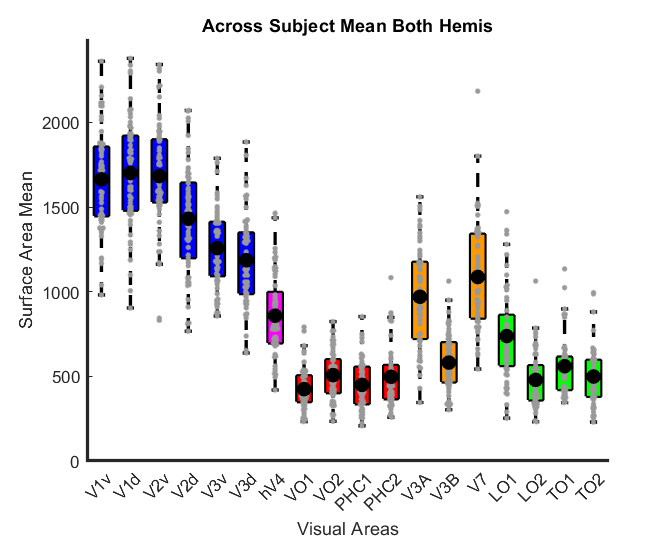

%% Plot distributions of area sizes
use_colorscale_inv=flipud(use_colorscale);
figure
hold on
h=boxplot(retino_surfacearea_smoothwm_bothhemis','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(use_colorscale_inv(j,:)),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_bothhemis','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_bothhemis'),'k.','MarkerSize',30);
xlim([0.5 size(retino_surfacearea_smoothwm_bothhemis,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_bothhemis.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

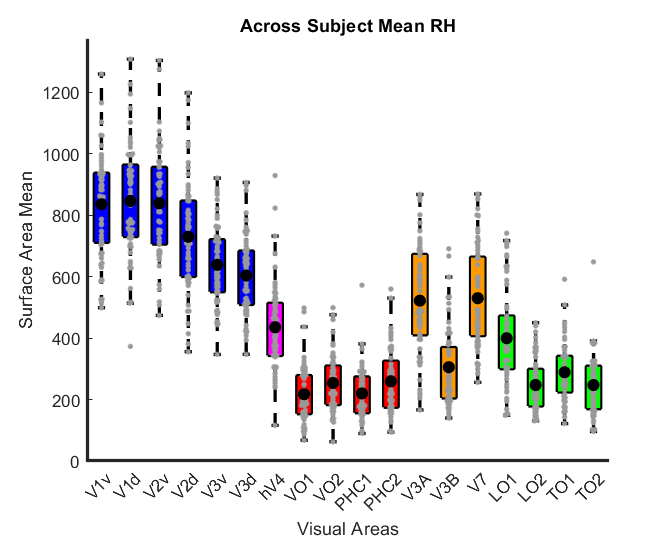

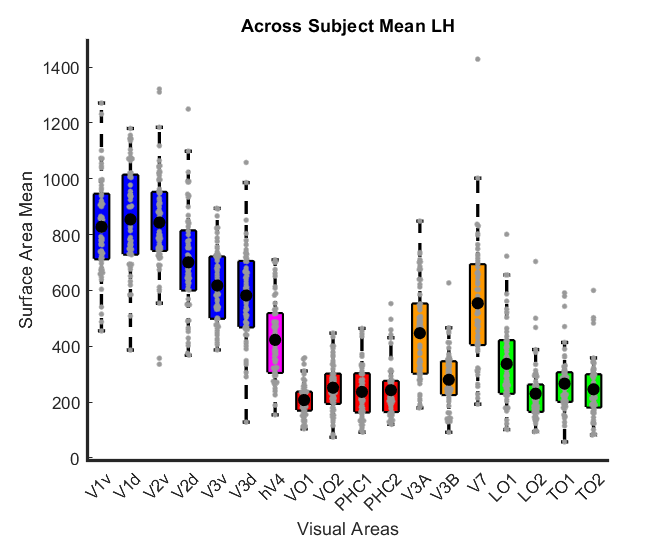

hemi_label = {'RH','LH'};
for i = 1:2
    figure
    hold on
    h=boxplot(retino_surfacearea_smoothwm{i}','notch','off','colors',[0 0 0],'symbol','');
    set(h,{'linew'},{2})
    h = findobj(gca,'Tag','Box');
     for j=1:length(h)
        patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
     end
    hold on
    plotSpread(retino_surfacearea_smoothwm{i}','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
    plot(nanmean(retino_surfacearea_smoothwm{i}'),'k.','MarkerSize',25);
    xlim([0.5 size(retino_surfacearea_smoothwm{i},1)+.5])
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    box off
    ax.XAxis.TickLength = [0 0];
    set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
    xlabel('Visual Areas');
    ylabel('Surface Area Mean');
    title(['Across Subject Mean ',hemi_label{i}])
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
    pngFileName = (['AcrossSubjectDistribution_',hemi_label{i},'.png']);
    fullFileName = fullfile(save_folder, pngFileName);
    saveas(gcf, fullFileName); 
end

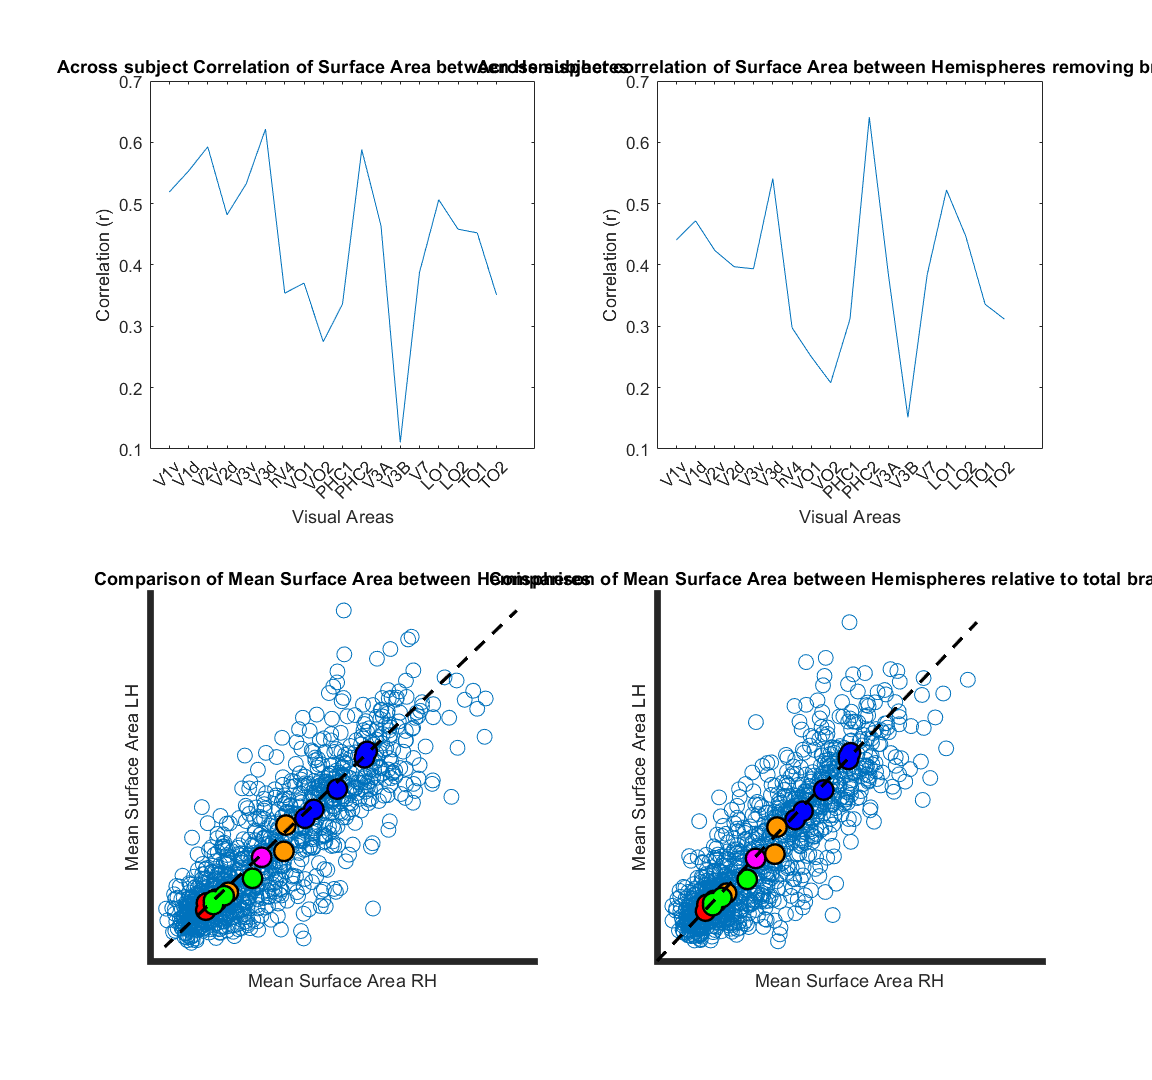

%% Comparisons of surface area between hemispheres
for curr_area = 1:size(retino_surfacearea_smoothwm{1},1)
    crosshemi_array(curr_area)=corr(retino_surfacearea_smoothwm{1}(curr_area,:)',retino_surfacearea_smoothwm{2}(curr_area,:)','rows','complete');
    crosshemi_array_control(curr_area)=corr((retino_surfacearea_smoothwm{1}(curr_area,:)./total_surfacearea{1})',(retino_surfacearea_smoothwm{2}(curr_area,:)./total_surfacearea{2})','rows','complete');   
end

figure
subplot(2,2,1)
plot(crosshemi_array)
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation (r)');
title('Across subject Correlation of Surface Area between Hemispheres')
subplot(2,2,2)
plot(crosshemi_array_control)
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation (r)');
title('Across subject correlation of Surface Area between Hemispheres removing brain size')
subplot(2,2,3)
scatter(retino_surfacearea_smoothwm{1}(:),retino_surfacearea_smoothwm{2}(:),80);
hold on
for rr = 1:length(allrois)
    plot(nanmean(retino_surfacearea_smoothwm{1}(allrois{rr},:),2),nanmean(retino_surfacearea_smoothwm{2}(allrois{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(retino_surfacearea_smoothwm{1}(allrois{rr},:),2),nanmean(retino_surfacearea_smoothwm{2}(allrois{rr},:),2),'.','Color',use_colorscale_unique(rr,:),'MarkerSize',35);
end
max_value=max([max(retino_surfacearea_smoothwm{1}(:)),max(retino_surfacearea_smoothwm{2}(:))]);
min_value=floor([min(retino_surfacearea_smoothwm{1}(:)),min(retino_surfacearea_smoothwm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
title('Comparison of Mean Surface Area between Hemispheres')
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .95, .65]);

subplot(2,2,4)
retino_surfacearea_smoothwm_norm{1}=retino_surfacearea_smoothwm{1}./total_surfacearea{1};
retino_surfacearea_smoothwm_norm{2}=retino_surfacearea_smoothwm{2}./total_surfacearea{2};
scatter(retino_surfacearea_smoothwm_norm{1}(:),retino_surfacearea_smoothwm_norm{2}(:),80);
hold on
for rr = 1:length(allrois)
    plot(nanmean(retino_surfacearea_smoothwm_norm{1}(allrois{rr},:),2),nanmean(retino_surfacearea_smoothwm_norm{2}(allrois{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(retino_surfacearea_smoothwm_norm{1}(allrois{rr},:),2),nanmean(retino_surfacearea_smoothwm_norm{2}(allrois{rr},:),2),'.','Color',use_colorscale_unique(rr,:),'MarkerSize',35);
end
%lsline
hold on
max_value=max([nanmax(retino_surfacearea_smoothwm_norm{1}(:)),nanmax(retino_surfacearea_smoothwm_norm{2}(:))]);
min_value=floor([nanmin(retino_surfacearea_smoothwm_norm{1}(:)),nanmin(retino_surfacearea_smoothwm_norm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])
title('Comparison of Mean Surface Area between Hemispheres relative to total brain size')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .6, .9]);
pngFileName = ('CrossHemisphereComparisons.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

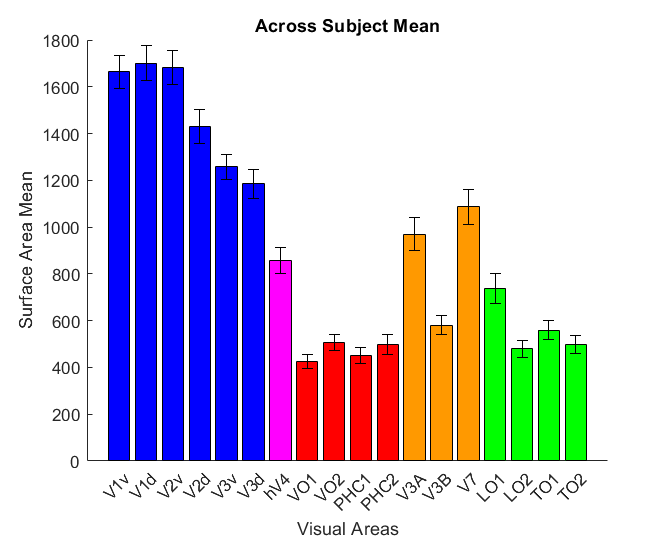

%% Bar graph showing across subject mean + standard error of surface area size for each visual area
figure
hold on;
for k = 1:length(allvisual_numbers)
    avgmeanbar = bar(k, mean_retinoareas_bothhemis(k),'FaceColor',use_colorscale(k,:));
end

set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean')

hold on
er = errorbar([1:length(allvisual_labels)],mean_retinoareas_bothhemis,stderror_retinoareas_bothhemis);    
er.Color = [0 0 0];                            
er.LineStyle = 'none'; 
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectMean.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

hold off

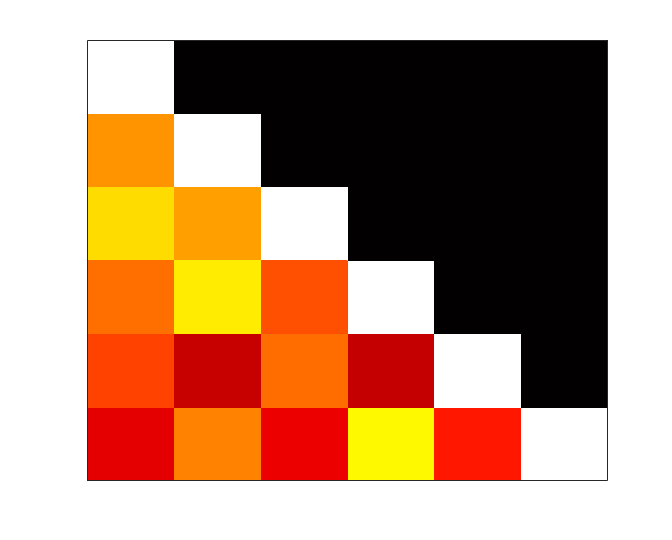

%% normalizing + plotting 

% For now, focus on nodearea smoothwm (add pial if you have time)
% run corr 
% to get around Nan: corr( X, Y, 'rows','complete')
% eg., corr( array of V3A sizes across subjects, array of V1 sizes)

%corr between all regions 

% hvae to create loop that takes each ROI from each subject --> nested for
% loops here --> okay 
%[rho,pval] = corr(V1_surfacearea, retino_surfacearea_smoothwm_bothhemis, 'complete');
%imagesc([r,l])

%normalize by V1 surface area 
%normalize by V1v surface area 
%normalize by V1d surface area

V1_surfacearea = (retino_surfacearea_smoothwm_bothhemis(1,:) + retino_surfacearea_smoothwm_bothhemis(2,:)); %full V1 of combined hemispheres 
V2_surfacearea = (retino_surfacearea_smoothwm_bothhemis(3,:) + retino_surfacearea_smoothwm_bothhemis(4,:)); %full V1 of combined hemispheres 
V3_surfacearea = (retino_surfacearea_smoothwm_bothhemis(5,:) + retino_surfacearea_smoothwm_bothhemis(6,:)); %full V1 of combined hemispheres 

V1v_surfacearea = retino_surfacearea_smoothwm_bothhemis(1,:);
V1d_surfacearea = retino_surfacearea_smoothwm_bothhemis(2,:);
V2v_surfacearea = retino_surfacearea_smoothwm_bothhemis(3,:);
V2d_surfacearea = retino_surfacearea_smoothwm_bothhemis(4,:);
V3v_surfacearea = retino_surfacearea_smoothwm_bothhemis(5,:);
V3d_surfacearea = retino_surfacearea_smoothwm_bothhemis(6,:);

if strcmp(species,'Monks')
    V4v_surfacearea = retino_surfacearea_smoothwm_bothhemis(7,:);
    V4d_surfacearea = retino_surfacearea_smoothwm_bothhemis(8,:);
    V4Av_surfacearea = retino_surfacearea_smoothwm_bothhemis(9,:);
    V4Ad_surfacearea = retino_surfacearea_smoothwm_bothhemis(10,:);
    DVcombined=[V1v_surfacearea;V1d_surfacearea;V2v_surfacearea;V2d_surfacearea;V3v_surfacearea;V3d_surfacearea;V4v_surfacearea;V4d_surfacearea;V4Av_surfacearea;V4Ad_surfacearea]  
else
    DVcombined=[V1v_surfacearea;V1d_surfacearea;V2v_surfacearea;V2d_surfacearea;V3v_surfacearea;V3d_surfacearea];
end

DVcombined_corr=corr(DVcombined','rows','complete');
DVcombined_corr(triu(true(size(DVcombined_corr,1)),1)) = 0;
imagesc(DVcombined_corr,[0 1])
colormap('hot')
set(gca,'xtick',[])
set(gca,'ytick',[])

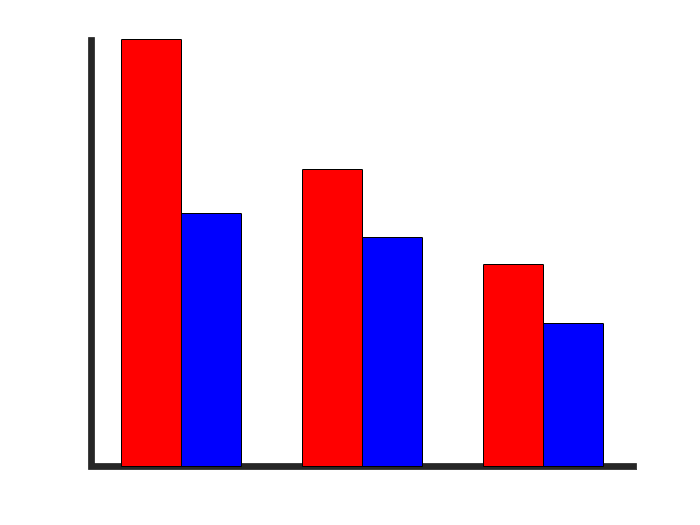


DVcombined_corr=corr(DVcombined','rows','complete');
figure 
hold on
bar([1, 4, 7], DVcombined_corr(1:2:6,1), .33 ,'r')
bar([2, 5, 8], DVcombined_corr(2:2:6,1), .33, 'b')
xlim([0 9])
ylim([0 1])
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])

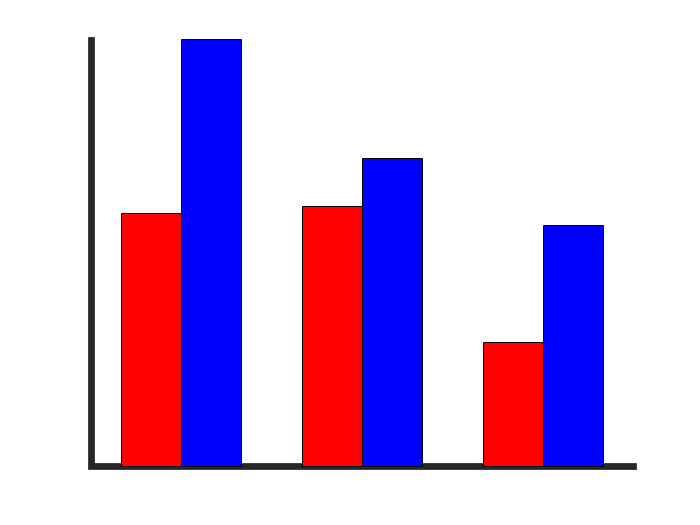


figure 
hold on
bar([1, 4, 7], DVcombined_corr(1:2:6,2), .33 ,'r')
bar([2, 5, 8], DVcombined_corr(2:2:6,2), .33, 'b')
xlim([0 9])
ylim([0 1])
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])

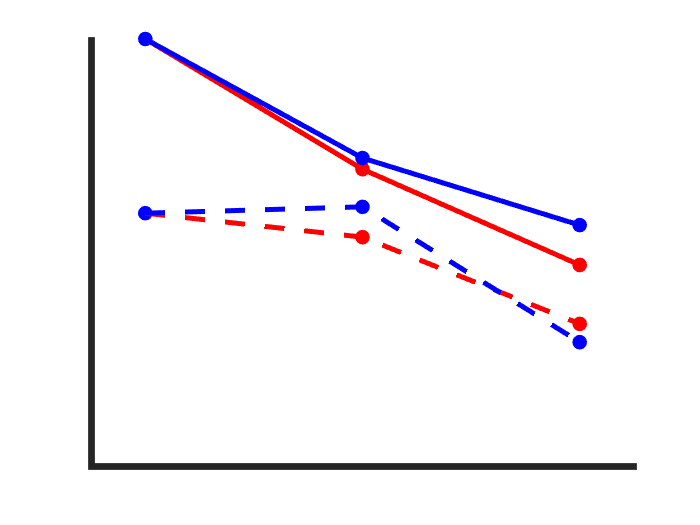


DVcombined_corr=corr(DVcombined','rows','complete');
if strcmp(species,'Monks')
    figure
    hold on
    plot(DVcombined_corr(1:2:10,1),'.r','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(2:2:10,2),'.b','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(2:2:10,1),'.r','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(1:2:10,2),'.b','LineWidth',3,'MarkerSize',30)

    plot(DVcombined_corr(1:2:10,1),'-r','LineWidth',3)
    plot(DVcombined_corr(2:2:10,2),'-b','LineWidth',3)
    plot(DVcombined_corr(2:2:10,1),'--r','LineWidth',3)
    plot(DVcombined_corr(1:2:10,2),'--b','LineWidth',3)
    xlim([.75 5.25])
    ylim([0 1])
    set(gca,'linewidth',4)
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    
else
    figure
    hold on
    plot(DVcombined_corr(1:2:6,1),'.r','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(2:2:6,2),'.b','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(2:2:6,1),'.r','LineWidth',3,'MarkerSize',30)
    plot(DVcombined_corr(1:2:6,2),'.b','LineWidth',3,'MarkerSize',30)

    plot(DVcombined_corr(1:2:6,1),'-r','LineWidth',3)
    plot(DVcombined_corr(2:2:6,2),'-b','LineWidth',3)
    plot(DVcombined_corr(2:2:6,1),'--r','LineWidth',3)
    plot(DVcombined_corr(1:2:6,2),'--b','LineWidth',3)
    xlim([.75 3.25])
    ylim([0 1])
    set(gca,'linewidth',4)
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    
end

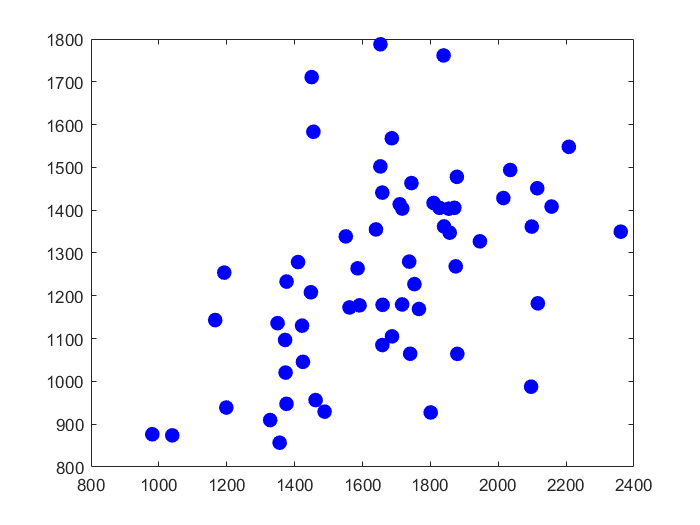


withinDV=[V1v_surfacearea,V1v_surfacearea,V2v_surfacearea;V2v_surfacearea,V3v_surfacearea,V3v_surfacearea];
betweenDV=[V1v_surfacearea,V1v_surfacearea,V2v_surfacearea;V2d_surfacearea,V3d_surfacearea,V3d_surfacearea];

V1DVcorrelations=[DVcombined_corr(1,:),DVcombined_corr(:,1)',DVcombined_corr(2,:),DVcombined_corr(:,2)'];
V1DVcorrelations=V1DVcorrelations(V1DVcorrelations>0 & V1DVcorrelations<1);

V2DVcorrelations=[DVcombined_corr(3,:),DVcombined_corr(:,3)',DVcombined_corr(4,:),DVcombined_corr(:,4)'];
V2DVcorrelations=V2DVcorrelations(V2DVcorrelations>0 & V2DVcorrelations<1);

V3DVcorrelations=[DVcombined_corr(5,:),DVcombined_corr(:,5)',DVcombined_corr(6,:),DVcombined_corr(:,6)'];
V3DVcorrelations=V3DVcorrelations(V3DVcorrelations>0 & V3DVcorrelations<1);

if strcmp(species,'Monks')
V4DVcorrelations=[DVcombined_corr(7,:),DVcombined_corr(:,7)',DVcombined_corr(8,:),DVcombined_corr(:,8)'];
V4DVcorrelations=V4DVcorrelations(V4DVcorrelations>0 & V4DVcorrelations<1);

V4ADVcorrelations=[DVcombined_corr(9,:),DVcombined_corr(:,9)',DVcombined_corr(10,:),DVcombined_corr(:,10)'];
V4ADVcorrelations=V4ADVcorrelations(V4ADVcorrelations>0 & V4ADVcorrelations<1);
end

figure
plot(V1v_surfacearea,V3v_surfacearea,'.b','Markersize',30)

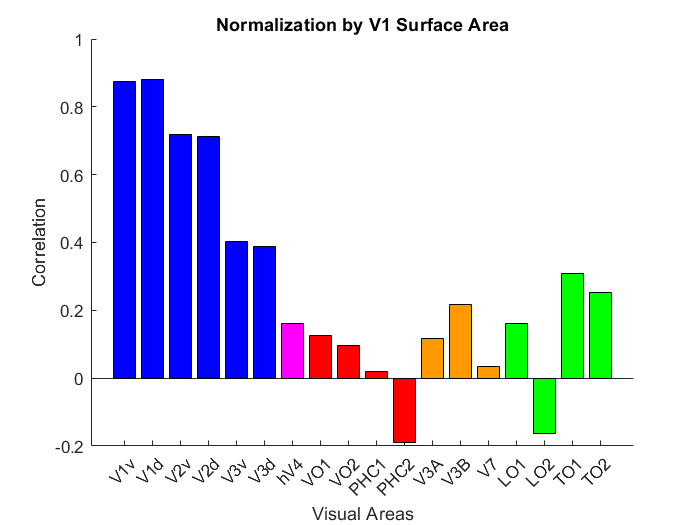


V3A_surfacearea = retino_surfacearea_smoothwm_bothhemis(7,:); %7 if Humans %11 if monks
 
%human areas
hV4_surfacearea = retino_surfacearea_smoothwm_bothhemis(14,:);
TO1_surfacearea = retino_surfacearea_smoothwm_bothhemis(12,:); 

%concatenated surfaceareas 
V1_surfacearea_cat = (retino_surfacearea_smoothwm_catbothhemis(1,:) + retino_surfacearea_smoothwm_catbothhemis(2,:));
V2_surfacearea_cat = (retino_surfacearea_smoothwm_catbothhemis(3,:) + retino_surfacearea_smoothwm_catbothhemis(4,:));
V3_surfacearea_cat = (retino_surfacearea_smoothwm_catbothhemis(5,:) + retino_surfacearea_smoothwm_catbothhemis(6,:));

N = size(retino_surfacearea_smoothwm_bothhemis, 1);

corr_V1 = corr(V1_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
hold on;

for k = 1:length(allvisual_numbers)
    barV1= bar(k,corr_V1(k),'FaceColor',use_colorscale(k,:));
end

set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1 Surface Area')

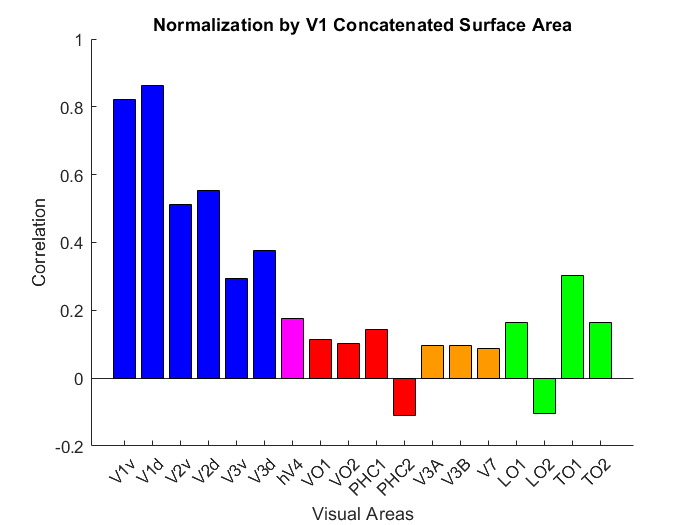


corr_V1_cat = corr(V1_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
figure
hold on;
for k = 1:length(allvisual_numbers)
    barV1cat= bar(k,corr_V1_cat(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1 Concatenated Surface Area')

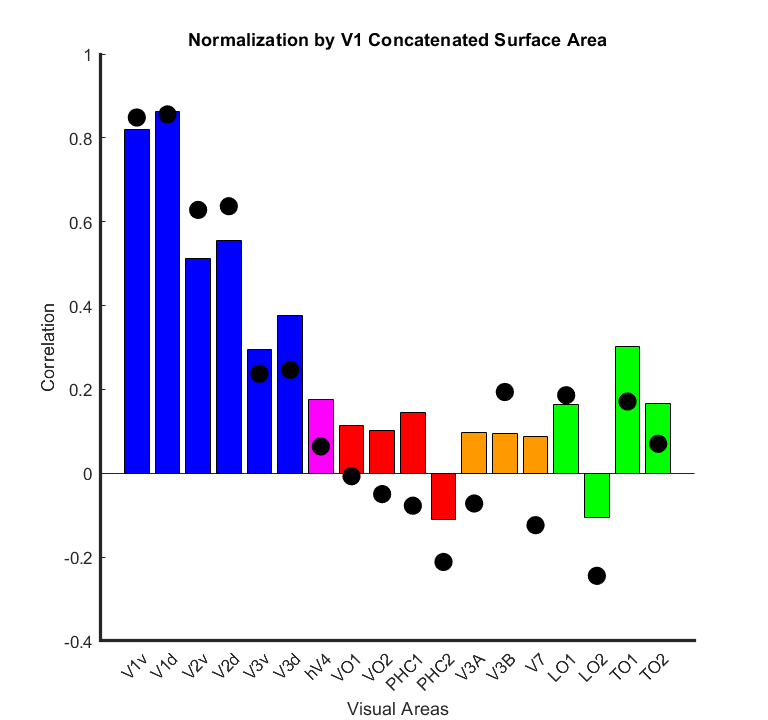


corr_V1_cat = corr(V1_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
figure
hold on
for k = 1:length(allvisual_numbers)
    b = bar(k,corr_V1_cat(k),'FaceColor',use_colorscale(k,:));
end

set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1 Concatenated Surface Area')
hold on
pcorr_V1 = partialcorr(V1_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
scatter([1:length(pcorr_V1)],pcorr_V1,'k','filled','SizeData',120)
hold off
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .4, .6]);
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];

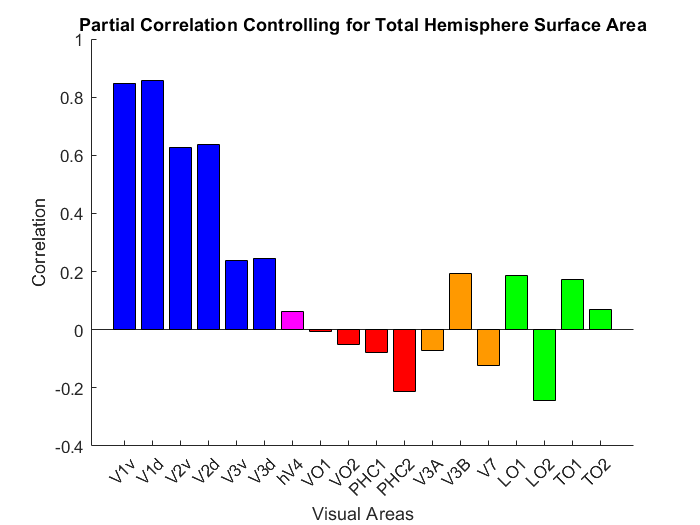


%partial corr V1: right and left hemisphere surface area
pcorr_V1 = partialcorr(V1_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
figure
hold on;
for k = 1:length(allvisual_numbers)
    barV1 = bar(k,pcorr_V1(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

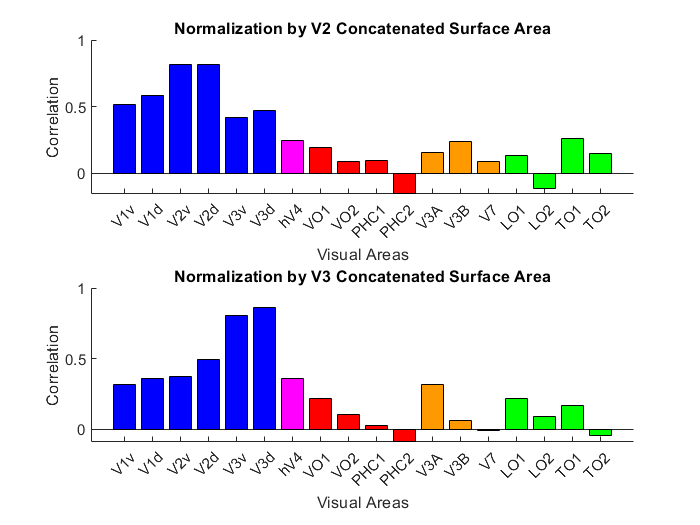

corr_V2_cat = corr(V2_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
figure
subplot(2,1,1)
hold on;
for k = 1:length(allvisual_numbers)
    barV2cat= bar(k,corr_V2_cat(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V2 Concatenated Surface Area')

corr_V3_cat = corr(V3_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
subplot(2,1,2)
hold on;
for k = 1:length(allvisual_numbers)
    barV3cat= bar(k,corr_V3_cat(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V3 Concatenated Surface Area')

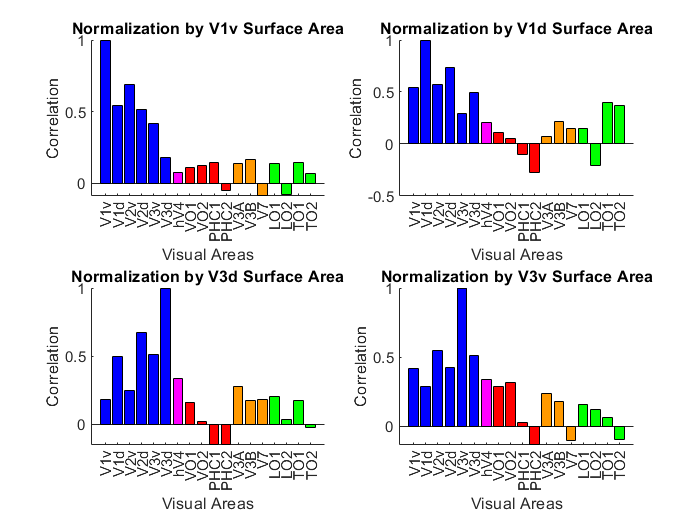


corr_V1v =  corr(V1v_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
subplot(2,2,1)
hold on;
for k = 1:length(allvisual_numbers)
    barV1v= bar(k,corr_V1v(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1v Surface Area')
corr_V1d = corr(V1d_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
subplot(2,2,2)
hold on;
for k = 1:length(allvisual_numbers)
    barV1d= bar(k,corr_V1d(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1d Surface Area')
corr_V3d = corr(V3d_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
subplot(2,2,3)
hold on;
for k = 1:length(allvisual_numbers)
    barV3d= bar(k,corr_V3d(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V3d Surface Area')
corr_V3v = corr(V3v_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
subplot(2,2,4)
hold on;
for k = 1:length(allvisual_numbers)
    barV3v= bar(k,corr_V3v(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V3v Surface Area')

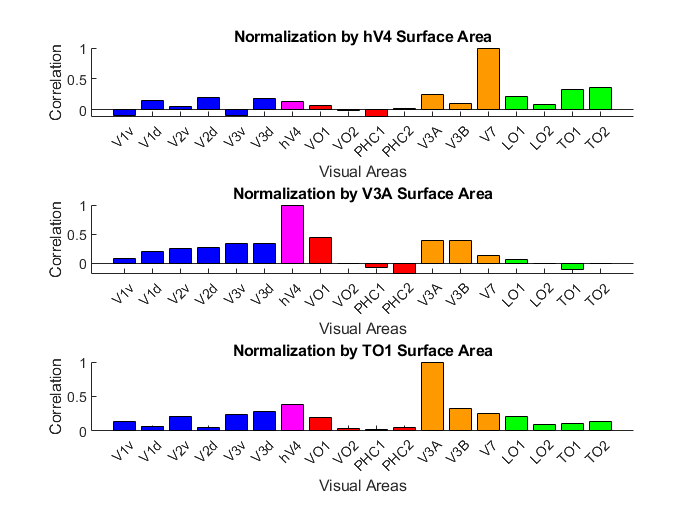

corr_hV4 = corr(hV4_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
figure
subplot(3,1,1)
hold on;
for k = 1:length(allvisual_numbers)
    barhV4= bar(k,corr_hV4(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by hV4 Surface Area')

corr_V3A = corr(V3A_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
subplot(3,1,2)
hold on;
for k = 1:length(allvisual_numbers)
    barV3A= bar(k,corr_V3A(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V3A Surface Area')

corr_TO1 = corr(TO1_surfacearea', retino_surfacearea_smoothwm_bothhemis', 'rows','complete');
subplot(3,1,3)
hold on;
for k = 1:length(allvisual_numbers)
    barTO1= bar(k,corr_TO1(k),'FaceColor',use_colorscale(k,:));
end
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by TO1 Surface Area')

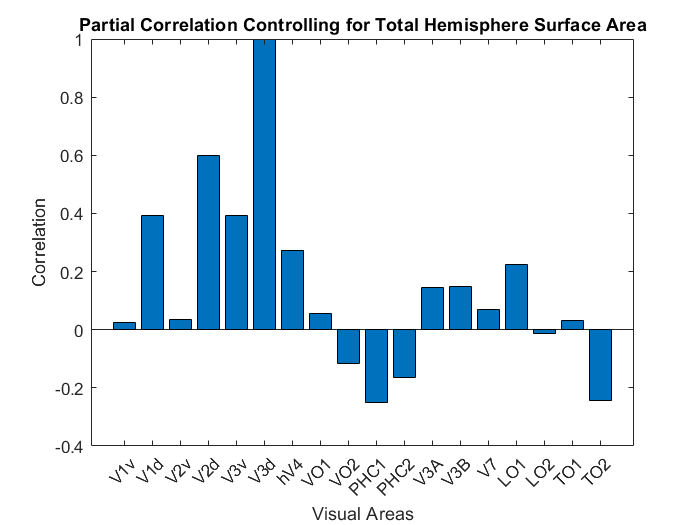

%% Partial Correlations 

%partial corr V3d: right and left hemisphere surface area
figure
pcorr_V3d = partialcorr(V3d_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV3d = bar([1:length(allvisual_labels)],pcorr_V3d);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

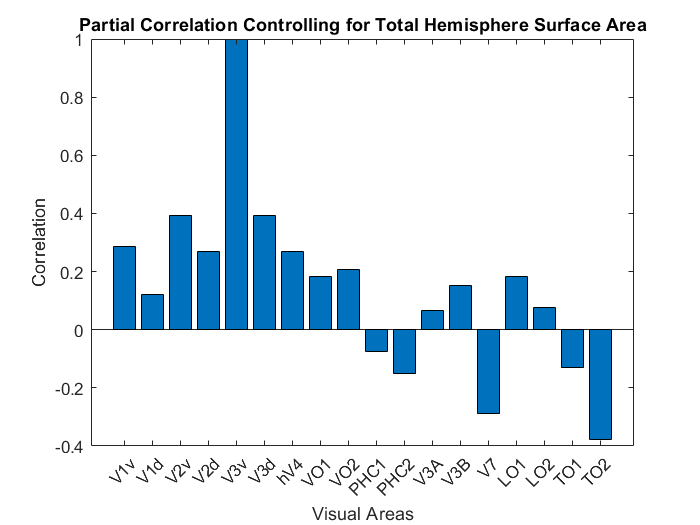


%partial corr V3v: right and left hemisphere surface area
figure
pcorr_V3v = partialcorr(V3v_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV3v = bar([1:length(allvisual_labels)],pcorr_V3v);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

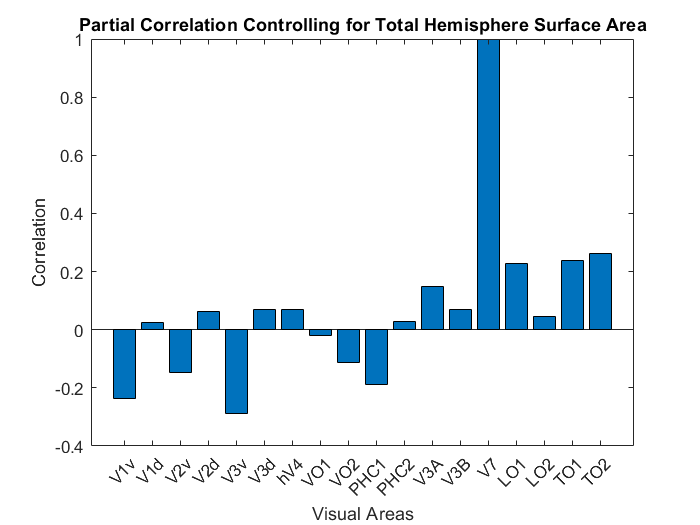



%partial corr hV4: right and left hemisphere surface area
figure
pcorr_hV4 = partialcorr(hV4_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barhV4 = bar([1:length(allvisual_labels)],pcorr_hV4);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

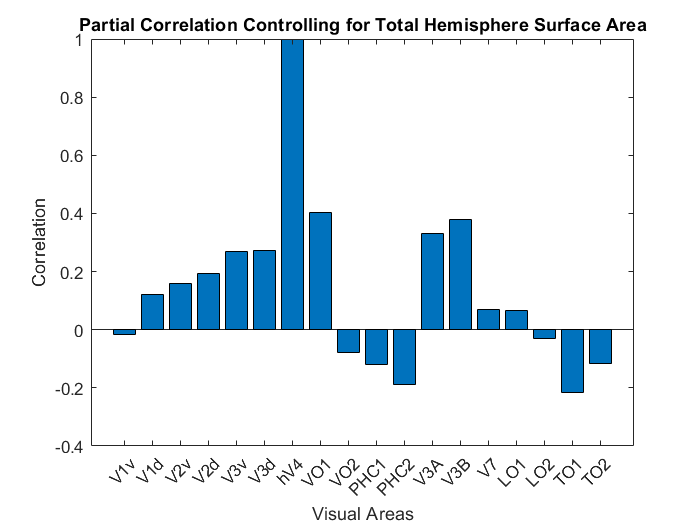



%partial corr V3A: right and left hemisphere surface area
figure
pcorr_V3A = partialcorr(V3A_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV3A = bar([1:length(allvisual_labels)],pcorr_V3A);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

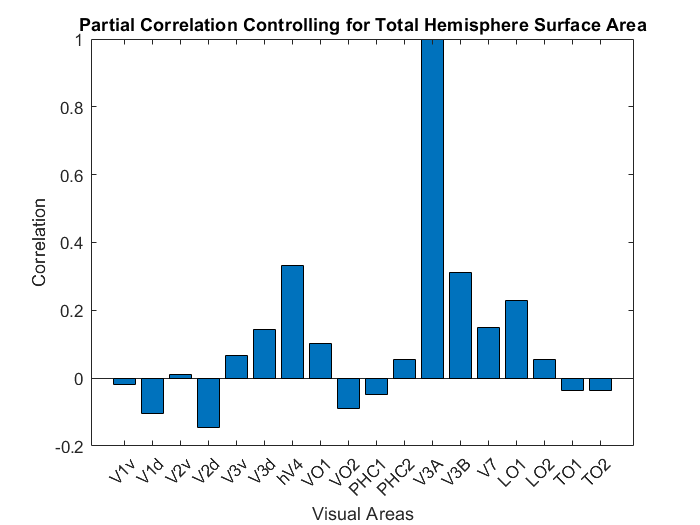



%partial corr TO1: right and left hemisphere surface area
figure
pcorr_TO1 = partialcorr(TO1_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barTO1 = bar([1:length(allvisual_labels)],pcorr_TO1);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

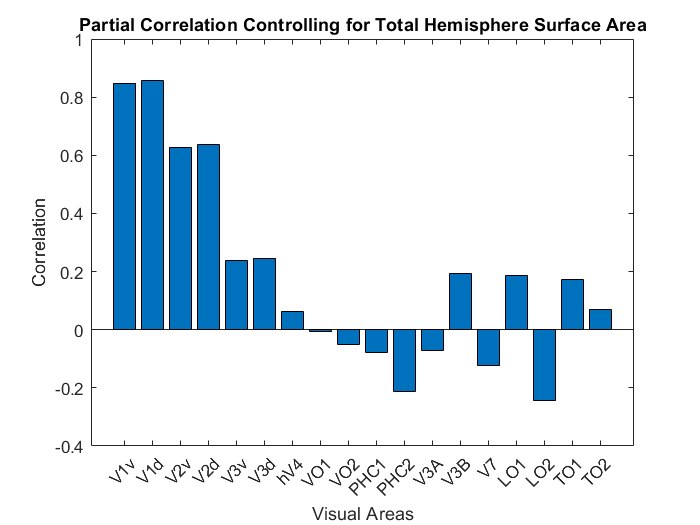



%partial corr V1: right and left hemisphere surface area
figure
pcorr_V1 = partialcorr(V1_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV1 = bar([1:length(allvisual_labels)],pcorr_V1);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

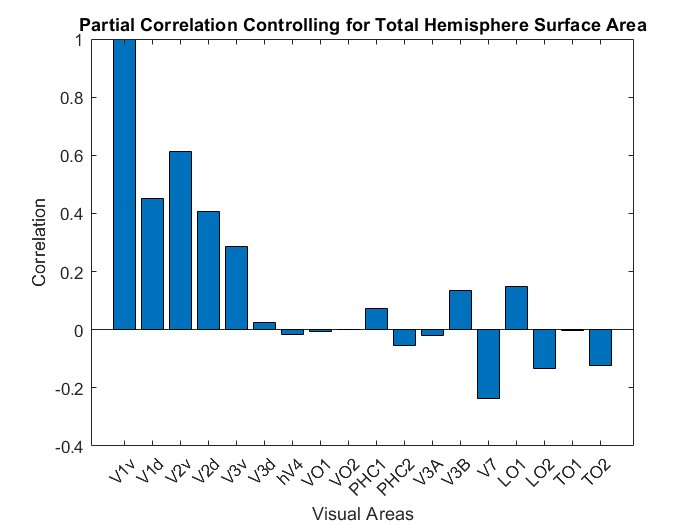



%partial corr V1v: right and left hemisphere surface area
figure
pcorr_V1v = partialcorr(V1v_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV1v = bar([1:length(allvisual_labels)],pcorr_V1v);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

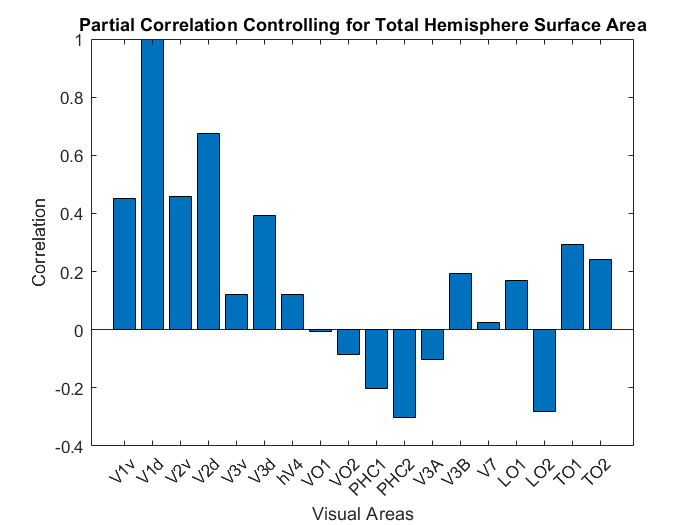


%partial corr V1d: right and left hemisphere surface area
figure
pcorr_V1d = partialcorr(V1d_surfacearea', retino_surfacearea_smoothwm_bothhemis', total_surfacearea_bothhemis', 'rows','complete');
barV1d = bar([1:length(allvisual_labels)],pcorr_V1d);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Partial Correlation Controlling for Total Hemisphere Surface Area')

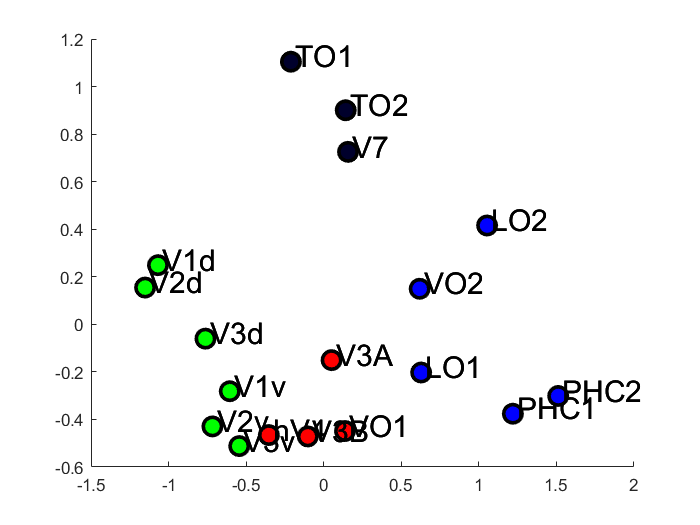



% RSA 
%just for humans? 
retino_surfacearea_simmatrix=corr(retino_surfacearea_smoothwm_bothhemis','rows','complete');
plotModularity(retino_surfacearea_simmatrix,allvisual_labels,'newmansq');

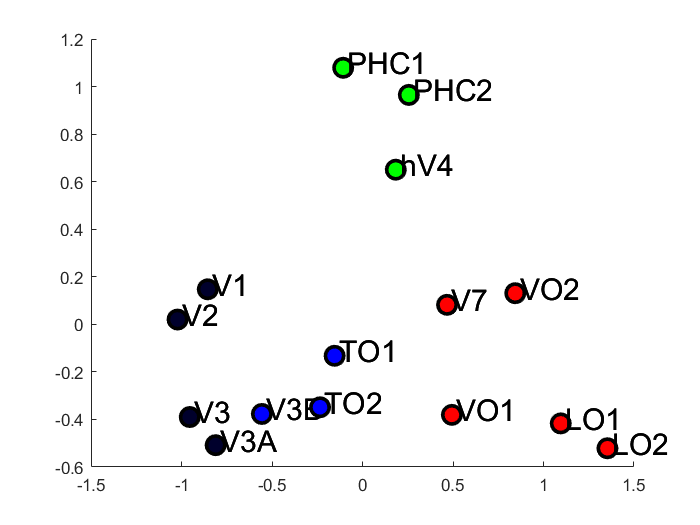


retino_surfacearea_smoothwm_bothhemis_noquadrants=retino_surfacearea_smoothwm_bothhemis;
retino_surfacearea_smoothwm_bothhemis_noquadrants(1,:)=retino_surfacearea_smoothwm_bothhemis_noquadrants(1,:)+retino_surfacearea_smoothwm_bothhemis_noquadrants(2,:);
retino_surfacearea_smoothwm_bothhemis_noquadrants(2,:)=retino_surfacearea_smoothwm_bothhemis_noquadrants(3,:)+retino_surfacearea_smoothwm_bothhemis_noquadrants(4,:);
retino_surfacearea_smoothwm_bothhemis_noquadrants(3,:)=retino_surfacearea_smoothwm_bothhemis_noquadrants(5,:)+retino_surfacearea_smoothwm_bothhemis_noquadrants(6,:);
retino_surfacearea_smoothwm_bothhemis_noquadrants(4,:)=[];
retino_surfacearea_smoothwm_bothhemis_noquadrants(5,:)=[];
retino_surfacearea_smoothwm_bothhemis_noquadrants(6,:)=[];
allvisual_labels_noquadrants={'V1','V2','V3','V3A','V3B','V7','LO1','LO2','TO1','TO2','hV4','VO1','VO2','PHC1','PHC2'};

retino_surfacearea_noquadrants_simmatrix=corr(retino_surfacearea_smoothwm_bothhemis_noquadrants','rows','complete');
plotModularity(retino_surfacearea_noquadrants_simmatrix,allvisual_labels_noquadrants,'newmansq');  %gives error when monks 

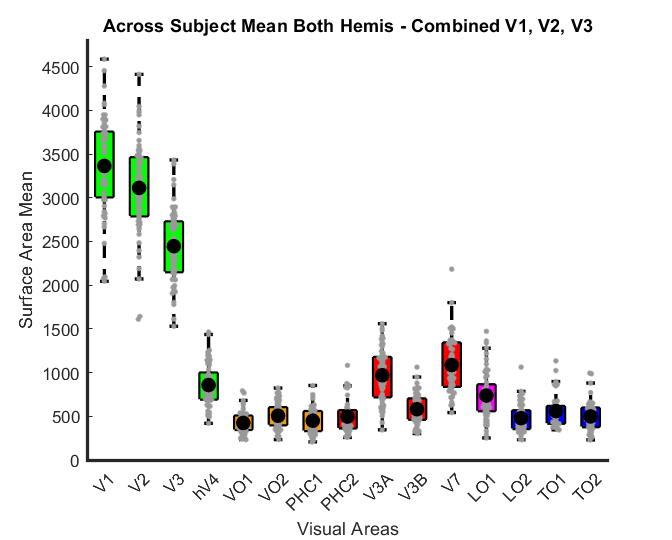

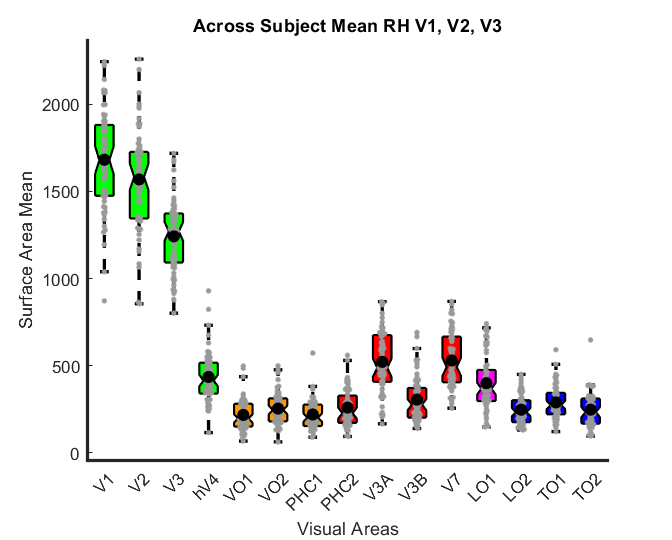

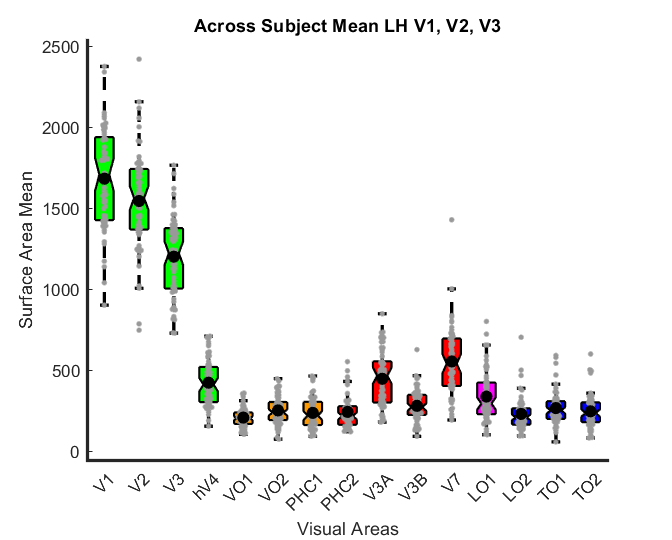

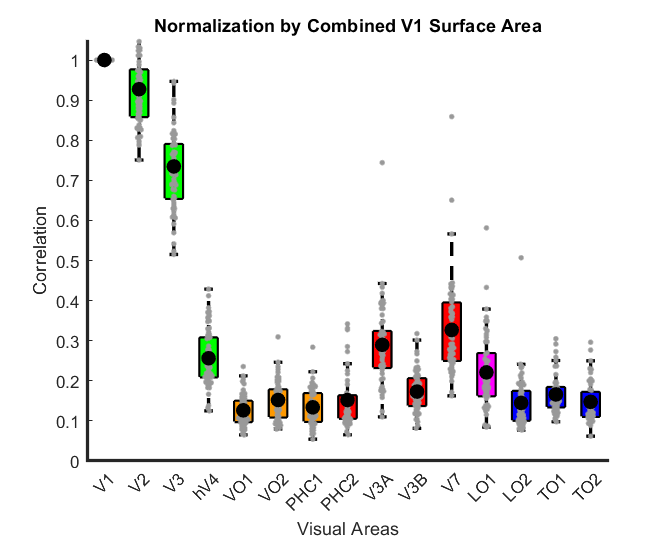

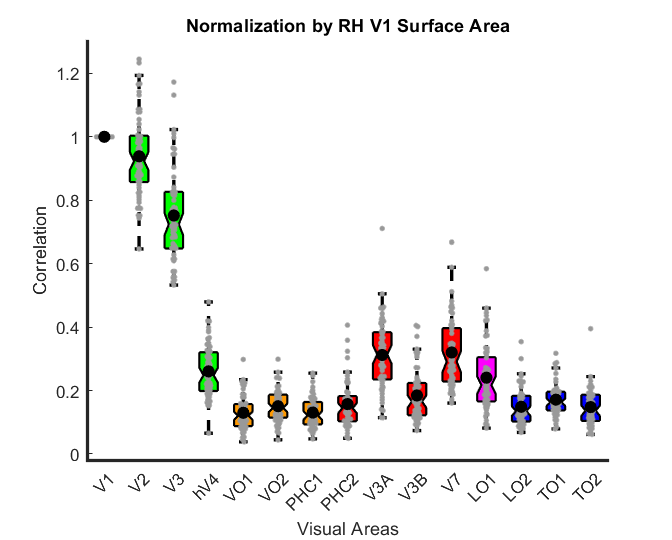

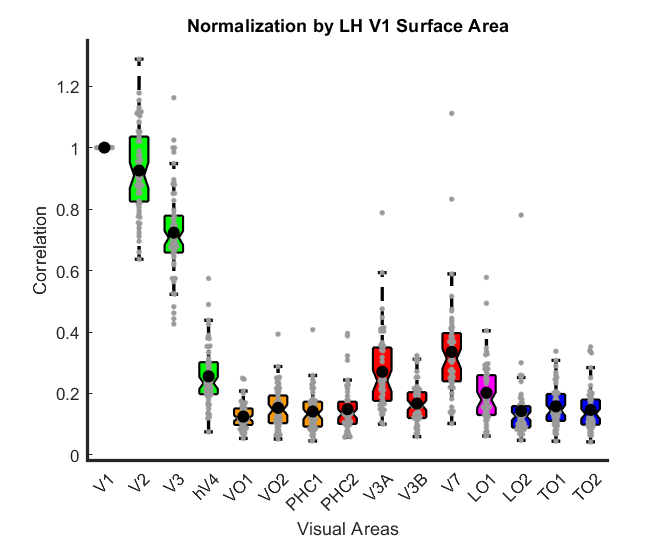

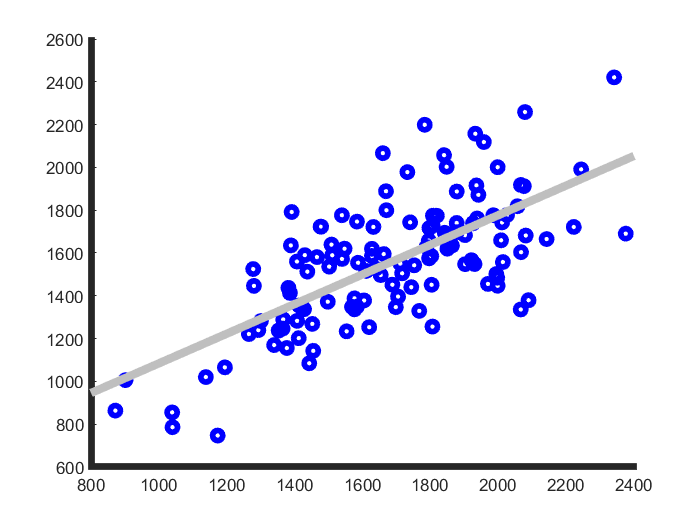

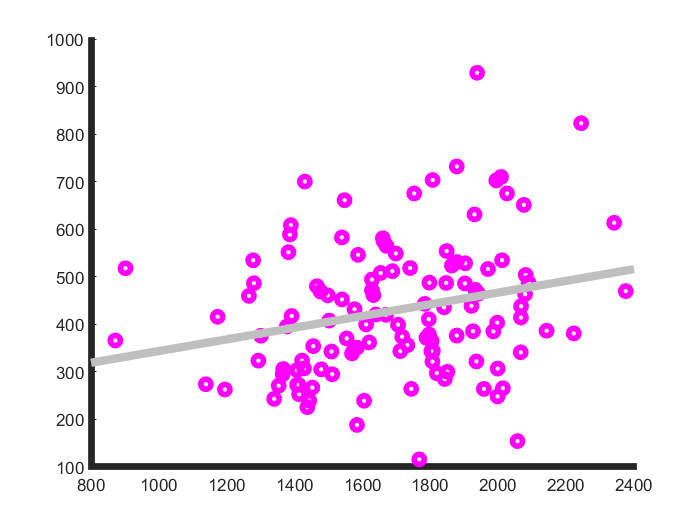



%% More direct Comparisons

monks = 0; %turn on/off certain graphs

%for monkeys 
if monks == 1 
    
allvisual_labels_combined_monks = {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};
%Combined V1, V2, V3, V4, V4A- monks
V1_bothhemis_combined = retino_surfacearea_smoothwm_bothhemis(1,:) + retino_surfacearea_smoothwm_bothhemis(2,:);
V2_bothhemis_combined = retino_surfacearea_smoothwm_bothhemis(3,:) + retino_surfacearea_smoothwm_bothhemis(4,:);
V3_bothhemis_combined = retino_surfacearea_smoothwm_bothhemis(5,:) + retino_surfacearea_smoothwm_bothhemis(6,:);
V4_bothhemis_combined = retino_surfacearea_smoothwm_bothhemis(7,:) + retino_surfacearea_smoothwm_bothhemis(8,:);
V4A_bothhemis_combined = retino_surfacearea_smoothwm_bothhemis(9,:) + retino_surfacearea_smoothwm_bothhemis(10,:);

retino_surfacearea_smoothwm_bothhemis_combinedV1234 = [V1_bothhemis_combined;V2_bothhemis_combined;V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;retino_surfacearea_smoothwm_bothhemis(11:26,:)]; 

figure
hold on
h=boxplot(retino_surfacearea_smoothwm_bothhemis_combinedV1234','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_bothhemis_combinedV1234','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234'),'k.','MarkerSize',30);
xlim([0.5 size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
ylim([0 2000])
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis - Combined V1, V2, V3, V4, V4A')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_bothhemis_combinedV1234.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

bar(nanstd(retino_surfacearea_smoothwm_bothhemis_combinedV1234,[],2)./nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234,2))

retino_surfacearea_smoothwm_bothhemis_combinedV1234_normV1=retino_surfacearea_smoothwm_bothhemis_combinedV1234./repmat(retino_surfacearea_smoothwm_bothhemis_combinedV1234(1,:),[size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1) 1]);
bar(nanstd(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normV1,[],2)./nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normV1,2))

retino_surfacearea_smoothwm_bothhemis_combinedV1234_normMT=retino_surfacearea_smoothwm_bothhemis_combinedV1234./repmat(retino_surfacearea_smoothwm_bothhemis_combinedV1234(13,:),[size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1) 1]);
bar(nanstd(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normMT,[],2)./nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normMT,2))

retino_surfacearea_bothhemis_combinedV1234_normtotalbrain=retino_surfacearea_smoothwm_bothhemis_combinedV1234./repmat(total_surfacearea_bothhemis(1,:),[size(retino_surfacearea_smoothwm_bothhemis_combinedV1234,1) 1]);

retino_surfacearea_smoothwm_bothhemis_combinedV1234_normbrainV1=retino_surfacearea_bothhemis_combinedV1234_normtotalbrain./repmat(retino_surfacearea_bothhemis_combinedV1234_normtotalbrain(1,:),[size(retino_surfacearea_bothhemis_combinedV1234_normtotalbrain,1) 1]);
bar(nanstd(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normbrainV1,[],2)./nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV1234_normbrainV1,2))


V1_catcombined = retino_surfacearea_smoothwm_catbothhemis(1,:) + retino_surfacearea_smoothwm_catbothhemis(2,:);
V2_catcombined = retino_surfacearea_smoothwm_catbothhemis(3,:) + retino_surfacearea_smoothwm_catbothhemis(4,:);
V3_catcombined = retino_surfacearea_smoothwm_catbothhemis(5,:) + retino_surfacearea_smoothwm_catbothhemis(6,:);
V4_catcombined = retino_surfacearea_smoothwm_catbothhemis(7,:) + retino_surfacearea_smoothwm_catbothhemis(8,:);
V4A_catcombined = retino_surfacearea_smoothwm_catbothhemis(9,:) + retino_surfacearea_smoothwm_catbothhemis(10,:);

retino_surfacearea_smoothwm_catbothhemis_combinedV123 = [V1_catcombined;V2_catcombined;V3_catcombined;V4_catcombined;V4A_catcombined;retino_surfacearea_smoothwm_catbothhemis(11:end,:)]; 
allvisual_labels_combined_monks = {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};
figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(2,:),10+x,'b')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];

figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(4,:),10+x,'m')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];


figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(18,:),10+x,'g')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];


% Separate Hemishpheres
for i = 1:2
    
    V1_combined{i} = retino_surfacearea_smoothwm{i}(1,:) + retino_surfacearea_smoothwm{i}(2,:);
    V2_combined{i} = retino_surfacearea_smoothwm{i}(3,:) + retino_surfacearea_smoothwm{i}(4,:);
    V3_combined{i} = retino_surfacearea_smoothwm{i}(5,:) + retino_surfacearea_smoothwm{i}(6,:);
    V4_combined{i} = retino_surfacearea_smoothwm{i}(7,:) + retino_surfacearea_smoothwm{i}(8,:);
    V4A_combined{i} = retino_surfacearea_smoothwm{i}(9,:) + retino_surfacearea_smoothwm{i}(10,:);
    
    retino_surfacearea_smoothwm_V1234{i} = [V1_combined{i};V2_combined{i};V3_combined{i};V4_combined{i};V4A_combined{i};retino_surfacearea_smoothwm{i}(11:26,:)]; 

    figure
    hold on
    h=boxplot(retino_surfacearea_smoothwm_V1234{i}','notch','off','colors',[0 0 0],'symbol','');
    set(h,{'linew'},{i})
    h = findobj(gca,'Tag','Box');
     for j=1:length(h)
        patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
     end
    hold on
    plotSpread(retino_surfacearea_smoothwm_V1234{i}','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
    plot(nanmean(retino_surfacearea_smoothwm_V1234{i}'),'k.','MarkerSize',30);
    xlim([0.5 size(retino_surfacearea_smoothwm_V1234{i},1)+.5])
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    box off
    ax.XAxis.TickLength = [0 0];
    set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
    xlabel('Visual Areas');
    ylabel('Surface Area Mean');
    title(['Across Subject Mean -',hemi_label{i},' V1, V2, V3, V4, V4A'])
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
    pngFileName = (['AcrossSubjectDistribution_',hemi_label{i},'_V1234.png']);
    fullFileName = fullfile(save_folder, pngFileName);
    saveas(gcf, fullFileName); 

end


%% Normalization by V1 graph - for each subject, divide other areas by V1 

%combined hemis V1
normv1_combined = retino_surfacearea_smoothwm_bothhemis_combinedV1234./V1_bothhemis_combined; 

figure
hold on
h=boxplot(normv1_combined','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale_inv(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(normv1_combined','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(normv1_combined'),'k.','MarkerSize',30);
xlim([0.5 size(normv1_combined,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
ylim([0 1])
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('Normalization_CombinedV1.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 


%separate hemi

for i = 1:2
    normv1{i} = retino_surfacearea_smoothwm_V1234{i}./V1_combined{i};
    
    figure
    hold on
    h=boxplot(normv1{i}','notch','on','colors',[0 0 0],'symbol','');
    set(h,{'linew'},{2})
    h = findobj(gca,'Tag','Box');
     for j=1:length(h)
        patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
     end
    hold on
    plotSpread(normv1{i}','distributionColors',flipud(use_colorscale)*.4,'spreadWidth',.5)
    plot(nanmean(normv1{i}'),'k.','MarkerSize',25);
    xlim([0.5 size(normv1{i},1)+.5])
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    box off
    ax.XAxis.TickLength = [0 0];
    set(gca,'xtick',[1:length(allvisual_labels_combined_monks)],'xticklabel', allvisual_labels_combined_monks);
    xlabel('Visual Areas');
    ylabel('Correlation');
    title(['Normalization by ',hemi_label{i},' V1 Surface Area'])
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
    pngFileName = (['Normalization_',hemi_label{i},'_V1.png']);
    fullFileName = fullfile(save_folder, pngFileName);
    saveas(gcf, fullFileName); 
end


else %plot human graphs 
    
allvisual_labels_combined = {'V1', 'V2', 'V3','hV4','VO1','VO2','PHC1','PHC2', 'V3A','V3B','V7','LO1','LO2','TO1','TO2'}; 
use_colorscale=[0 0 1; 0 0 1; 0 0 1; 1 0 1; 1 0 0; 1 0 0; 1 0 0; 1 0 0; 1 .6 0; 1 .6 0; 1 .6 0; 0 1 0; 0 1 0; 0 1 0; 0 1 0];
use_colorscale_inv = fliplr(use_colorscale);
%Combined V1, V2, V3 
V1_bothhemis_combined = retino_surfacearea_smoothwm_bothhemis(1,:) + retino_surfacearea_smoothwm_bothhemis(2,:);
V2_bothhemis_combined = retino_surfacearea_smoothwm_bothhemis(3,:) + retino_surfacearea_smoothwm_bothhemis(4,:);
V3_bothhemis_combined = retino_surfacearea_smoothwm_bothhemis(5,:) + retino_surfacearea_smoothwm_bothhemis(6,:);

retino_surfacearea_smoothwm_bothhemis_combinedV123 = [V1_bothhemis_combined;V2_bothhemis_combined;V3_bothhemis_combined;retino_surfacearea_smoothwm_bothhemis(7:18,:)]; 

figure
hold on
h=boxplot(retino_surfacearea_smoothwm_bothhemis_combinedV123','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(retino_surfacearea_smoothwm_bothhemis_combinedV123','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(retino_surfacearea_smoothwm_bothhemis_combinedV123'),'k.','MarkerSize',30);
xlim([0.5 size(retino_surfacearea_smoothwm_bothhemis_combinedV123,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis - Combined V1, V2, V3')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
pngFileName = ('AcrossSubjectDistribution_bothhemis_combinedV123.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 

%Separate Hemishpheres
for i = 1:2
    V1_combined{i} = retino_surfacearea_smoothwm{i}(1,:) + retino_surfacearea_smoothwm{i}(2,:);
    V2_combined{i} = retino_surfacearea_smoothwm{i}(3,:) + retino_surfacearea_smoothwm{i}(4,:);
    V3_combined{i} = retino_surfacearea_smoothwm{i}(5,:) + retino_surfacearea_smoothwm{i}(6,:);
    
    retino_surfacearea_smoothwm_V123{i} = [V1_combined{i};V2_combined{i};V3_combined{i};retino_surfacearea_smoothwm{i}(7:18,:)]; 
    
    figure
    hold on
    h=boxplot(retino_surfacearea_smoothwm_V123{i}','notch','on','colors',[0 0 0],'symbol','');
    set(h,{'linew'},{2})
    h = findobj(gca,'Tag','Box');
     for j=1:length(h)
        patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
     end
    hold on
    plotSpread(retino_surfacearea_smoothwm_V123{i}','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
    plot(nanmean(retino_surfacearea_smoothwm_V123{i}'),'k.','MarkerSize',25);
    xlim([0.5 size(retino_surfacearea_smoothwm_V123{i},1)+.5])
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    box off
    ax.XAxis.TickLength = [0 0];
    set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
    xlabel('Visual Areas');
    ylabel('Surface Area Mean');
    title(['Across Subject Mean ',hemi_label{i},' V1, V2, V3'])
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
    pngFileName = (['AcrossSubjectDistribution_',hemi_label{i},'_V123.png']);
    fullFileName = fullfile(save_folder, pngFileName);
    saveas(gcf, fullFileName); 
end


%Normalization by V1 graph - for each subject, divide other areas by V1 

%combined hemis V1
normv1_combined = retino_surfacearea_smoothwm_bothhemis_combinedV123./V1_bothhemis_combined;

figure
hold on
h=boxplot(normv1_combined','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
 for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
 end
hold on
plotSpread(normv1_combined','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(normv1_combined'),'k.','MarkerSize',30);
xlim([0.5 size(normv1_combined,1)+.5])
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 1.05])
pngFileName = ('Normalization_CombinedV1.png');
fullFileName = fullfile(save_folder, pngFileName);
saveas(gcf, fullFileName); 



%separate hemis
for i = 1:2
    normv1{i} = retino_surfacearea_smoothwm_V123{i}./V1_combined{i};
    figure
    hold on
    h=boxplot(normv1{i}','notch','on','colors',[0 0 0],'symbol','');
    set(h,{'linew'},{2})
    h = findobj(gca,'Tag','Box');
     for j=1:length(h)
        patch(get(h(j),'XData'),get(h(j),'YData'),use_colorscale(j,:),'FaceAlpha',1);
     end
    hold on
    plotSpread(normv1{i}','distributionColors',use_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
    plot(nanmean(normv1{i}'),'k.','MarkerSize',25);
    xlim([0.5 size(normv1{i},1)+.5])
    ax = gca;
    ax.XRuler.Axle.LineWidth = 2;
    ax.YRuler.Axle.LineWidth = 2;
    box off
    ax.XAxis.TickLength = [0 0];
    set(gca,'xtick',[1:length(allvisual_labels_combined)],'xticklabel', allvisual_labels_combined);
    xlabel('Visual Areas');
    ylabel('Correlation');
    title(['Normalization by ',hemi_label{i},' V1 Surface Area'])
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
    pngFileName = (['Normalization_',hemi_label{i},'_V1.png']);
    fullFileName = fullfile(save_folder, pngFileName);
    saveas(gcf, fullFileName); 
end


V1_catcombined = retino_surfacearea_smoothwm_catbothhemis(1,:) + retino_surfacearea_smoothwm_catbothhemis(2,:);
V2_catcombined = retino_surfacearea_smoothwm_catbothhemis(3,:) + retino_surfacearea_smoothwm_catbothhemis(4,:);
V3_catcombined = retino_surfacearea_smoothwm_catbothhemis(5,:) + retino_surfacearea_smoothwm_catbothhemis(6,:);

retino_surfacearea_smoothwm_catbothhemis_combinedV123 = [V1_catcombined;V2_catcombined;V3_catcombined;retino_surfacearea_smoothwm_catbothhemis(7:end,:)]; 

% for curr_roi=1:size(retino_surfacearea_smoothwm_catbothhemis_combinedV123,1)
%     V1corrs(curr_roi)=corr(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,~isnan(retino_surfacearea_smoothwm_catbothhemis_combinedV123(curr_roi,:)))',retino_surfacearea_smoothwm_catbothhemis_combinedV123(curr_roi,~isnan(retino_surfacearea_smoothwm_catbothhemis_combinedV123(curr_roi,:)))');
% end

figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(2,:),10+x,'b')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];

figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(4,:),10+x,'m')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];


figure
hold on
for x = 1:70
    scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:),retino_surfacearea_smoothwm_catbothhemis_combinedV123(14,:),10+x,'g')
end
h2 = lsline;
h2(1).LineWidth = 5;
ax = gca;
ax.XRuler.Axle.LineWidth = 4;
ax.YRuler.Axle.LineWidth = 4;
box off
ax.XAxis.TickLength = [0 0];

figure
hold on
scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:)/nanmean(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:)),retino_surfacearea_smoothwm_catbothhemis_combinedV123(2,:)/nanmean(retino_surfacearea_smoothwm_catbothhemis_combinedV123(2,:)),80)
scatter(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:)/nanmean(retino_surfacearea_smoothwm_catbothhemis_combinedV123(1,:)),retino_surfacearea_smoothwm_catbothhemis_combinedV123(4,:)/nanmean(retino_surfacearea_smoothwm_catbothhemis_combinedV123(4,:)),80)

corr_V1_cat = corr(V1_surfacearea_cat', retino_surfacearea_smoothwm_catbothhemis', 'rows','complete');
figure
barV1cat= bar([1:length(allvisual_labels)],corr_V1_cat);
set(gca,'xtick',[1:length(allvisual_labels)],'xticklabel', allvisual_labels);
xlabel('Visual Areas');
ylabel('Correlation');
title('Normalization by V1 Concatenated Surface Area')

end

## this part has a bug/doesn't make sense

% allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,52,53,54,55,56,100,101,102,103];
% 
% meanavgdist_allsubjs_rh=nanmean(avgdist_allsubjs_rh,2);
% meanavgdist_allsubjs_lh=nanmean(avgdist_allsubjs_lh,2);
% rh_rois=Read_1D('allvisual-rh.1D.dset');
% lh_rois=Read_1D('allvisual-lh.1D.dset');
% rh_avgdist_rois=rh_rois;
% rh_avgdist_rois(rh_rois(:,2)==1,2)=0.05;
% rh_avgdist_rois(rh_rois(:,2)==2,2)=0.05;
% lh_avgdist_rois=lh_rois;
% lh_avgdist_rois(lh_rois(:,2)==1,2)=0.05;
% lh_avgdist_rois(lh_rois(:,2)==2,2)=0.05;
% for curr_roi = 3: length(allvisual_numbers)
%     rh_avgdist_rois(rh_rois(:,2)==allvisual_numbers(curr_roi),2)=meanavgdist_allsubjs_rh(curr_roi);
%     lh_avgdist_rois(lh_rois(:,2)==allvisual_numbers(curr_roi),2)=meanavgdist_allsubjs_lh(curr_roi);
% end
% 
% dlmwrite('rh_avgdist_rois.1D.dset',rh_avgdist_rois)
% dlmwrite('lh_avgdist_rois.1D.dset',lh_avgdist_rois)

% eg., partialcorr( array of V3A sizes across subjects, array of V1 sizes, array total surface area)
% across subjects)

% create correlation matrix: area x area correlations
% create partial correlation matrix: area x area correlations removing
% total area
% create partial correlation matrix: area x area correlations removing
% V1 area
